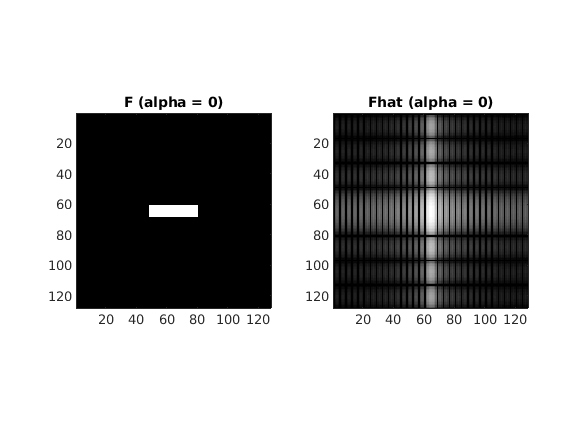

% q11
     F = [zeros(60, 128); ones(8, 128); zeros(60, 128)] .* [zeros(128, 48) ones(128, 32) zeros(128, 48)];
     subplot(1,2,1)
     showgrey(F)
     title("F (alpha = " + 0 +")")
     axis on
     
     subplot(1,2,2)
     showfs(fft2(F))
     title("Fhat (alpha = " + 0 + ")")
     axis on

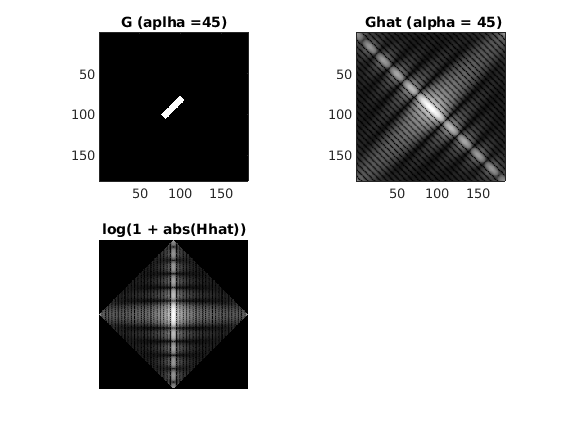


% q12

for alpha = [45] % rotation, change between 30, 45, 60 and 90.
    
    G = rot(F, alpha); 
    subplot(2, 2, 1)
    showgrey(G)
    axis on
    title("G (aplha =" + alpha + ")")
     
    Ghat = fft2(G);
    subplot(2, 2, 2)
    showfs(Ghat)
    axis on
    title(" Ghat (alpha = " + alpha + ")")    
      
    subplot(2, 2, 3)
    Hhat = rot(fftshift(Ghat), -alpha); % rotate back
    
    showgrey(log(1 + abs(Hhat))) % to smooth tha amplitude to include all of it.
    title("log(1 + abs(Hhat))")
    
    %subplot(2, 2, 4)
    %showfs(ifft(Ghat))
end